# Robótica Taller 3

*Daniel Esteban Ramirez Chiquillo*

*dramirezch@unal.edu.co*

## *1*

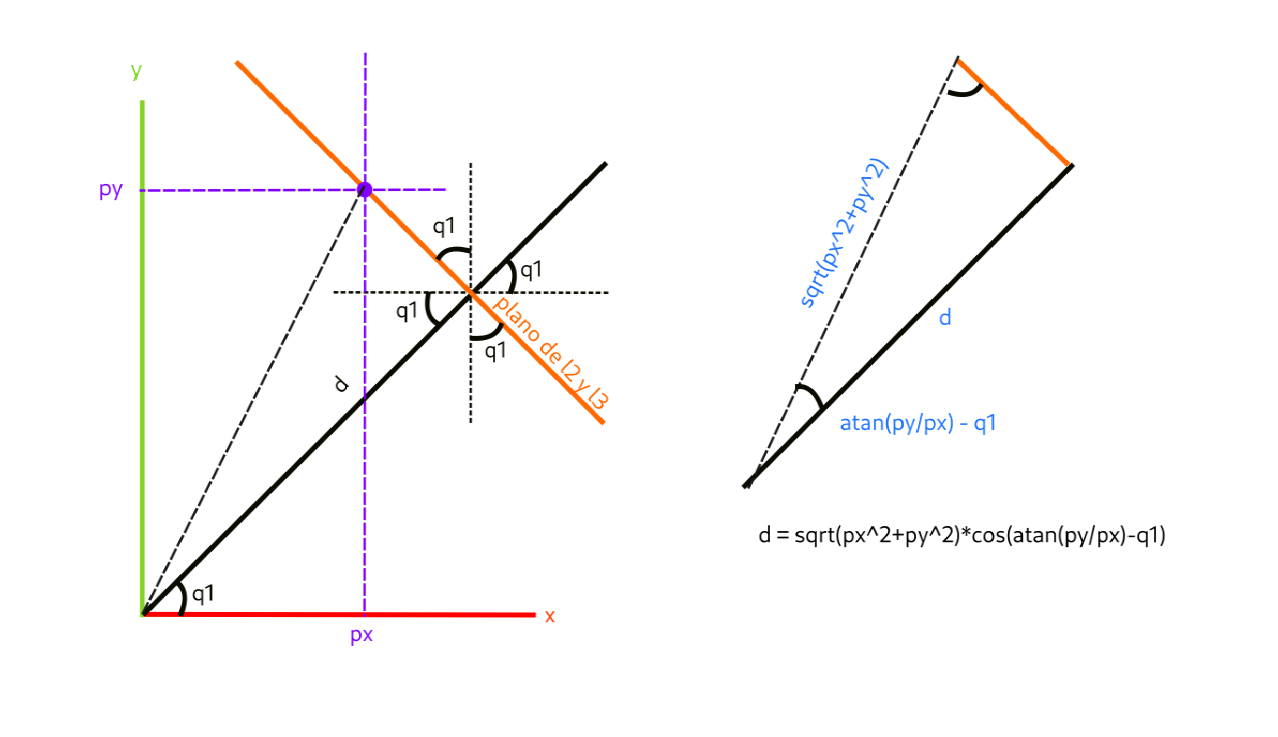

clc
clear
% dimensiones del robot
syms l1 l2 l3 d 
% target
syms px py pz 
% Para encontrar q1:
imshow("punto_1_q1.png")

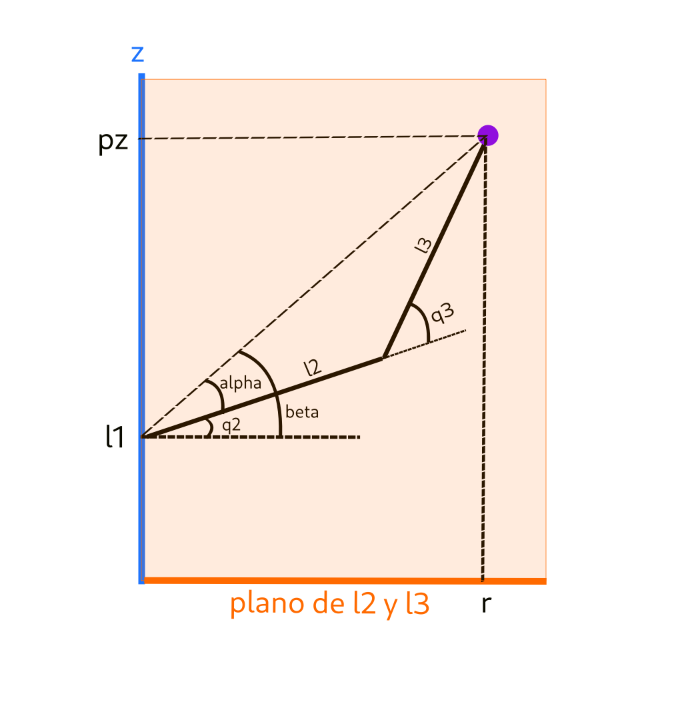

syms q1
q1 = solve(d == sqrt(px^2+py^2)*cos(atan2(py,px)-q1), q1);
% q1=q1(1); % no sé por qué, q1(2) suele ser un ang erróneo
% Radio del plano de trabajo
dx = d.*cos(q1);
dy = d.*sin(q1);
r = sqrt((dx-px).^2+(dy-py).^2);
imshow("punto_1_plano.png")

% Para encontrar q3:
cq3 = (r.^2+(pz-l1).^2-l2.^2-l3.^2)./(2.*l2.*l3); % por ley del coseno
sq3 = [sqrt(1-cq3.^2) -sqrt(1-cq3.^2)]'; % se deben considerar positivo y negativo
q3 = atan2(sq3,cq3); % es mejor usar atan2 que acos
% Para encontrar q2:
beta = [atan2((pz-l1),r) atan2((pz-l1),-r) ]; % r es una sqrt, hay que considerar + y -
alpha = atan2((l3.*sin(q3)),(l2+l3.*cos(q3)));
q2 = beta - alpha;

***Existen 2 posibles soluciones para q1, 4 para q2 y 4 para q3***, en el intervalo dado***. ***Esto permite obtener hasta 4 posibles configuraciones para un punto dado. Se aclara que "solo" son 4 configuraciones porque las posibles soluciones no son compatibles "todas con todas". Por ejemplo, para la siguiente configuración:

l1=1;l2=1;l3=1;d=1;
px=1;py=1;pz=2;
eval(q1)';
eval(q2);
eval(q3);

Se puede obtener una configuración válida siguiendo el siguiente procedimiento:

- Escoger un valor de q1.

- Si se escogió el valor 1, se toma la primera columna de q2 y q3. Si se escogió el segundo, se toma la segunda.

- Se escoge un valor de q2 de la columna escogida.

- Si se escogío el valor 1, se toma el primer valor de q3 (de la columna escogida). Si se escogió el valor 2, se toma el segundo.

## 2

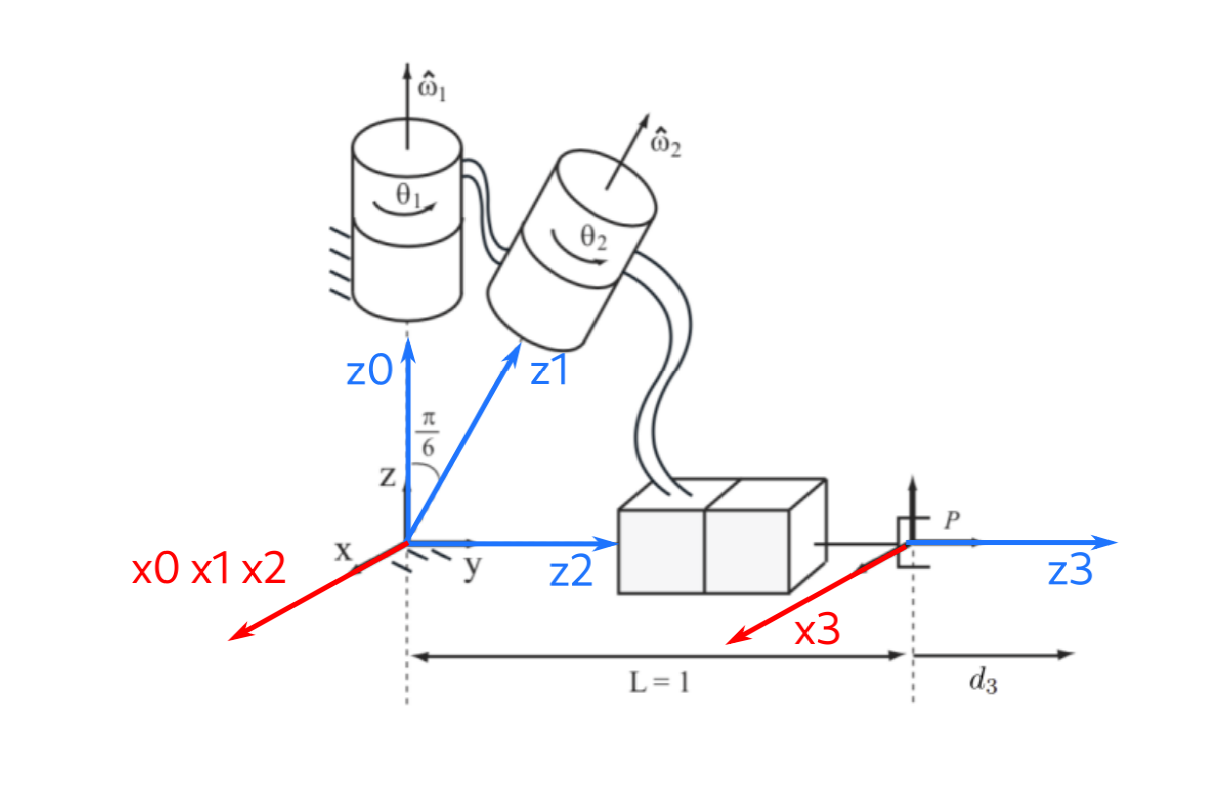

clc
clear
% target
syms q1 q2 d3
% fkine
imshow("punto_2.png")

l1 = Link ('revolute', 'd', 0, 'a', 0, 'alpha', -pi/6 , 'offset', 0);
l2 = Link ('revolute', 'd', 0, 'a', 0, 'alpha', -(pi/2-pi/6), 'offset', 0);
l3 = Link ('prismatic', 'theta' , 0, 'a', 0, 'alpha', 0, 'offset', 1, 'qlim', 0);
SerialLink([l1 l2 l3]', 'name', 'Ejercicio 2')

 
ans = 
 
Ejercicio 2:: 3 axis, RRP, stdDH, slowRNE                        
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|  -0.523599|          0|
|  2|         q2|          0|          0|    -1.0472|          0|
|  3|          0|         q3|          0|          0|          1|
+---+-----------+-----------+-----------+-----------+-----------+
 


% matriz de cada articulación
a01 = l1.A(q1);
a12 = l2.A(q2);
a23 = l3.A(d3);

### A

% matriz de todo el sistema
Ta = l1.A(0)*a12*a23;
% ecuaciones
eq1=-((sqrt(3)*sin(q2)*(d3+1))/(2))==-6;
eq2=(((3*cos(q2))/4)+1/4)*(d3+1)==5;
eq3=(sqrt(3)/4-sqrt(3)*cos(q2)/4)*(d3+1)==sqrt(3);
% solución
solve([eq1, eq2, eq3], [q1, q2, d3])

ans = struct with fields:
    q1: 0
    q2: pi/3
    d3: 7


### B

% matriz de todo el sistema
Tb = a01*a12*a23;
% ecuaciones
o1=(sqrt(3)*cos(q1)*sin(q2))/2;
o2=(sqrt(3)/4)-((sqrt(3)*cos(q2))/4);
o3=(3*cos(q2)*sin(q1))/4;
o5=(sqrt(3)*sin(q1)*sin(q2))/2;
o4=(cos(q1))/4+(3*cos(q1)*cos(q2))/4-o5;
eq1=-(d3+1)*(sin(q1)/4+o3+o1)==-6;
eq2=(d3+1)*o4==5;
eq3=(d3+1)*o2==sqrt(3);
% solución
[q1, q2, d3] = solve([eq1, eq2, eq3], [q1, q2, d3]);

2 de las soluciones contienen números imaginarios y valores negativos de d3, lo cual no es posible. Las 2 soluciones posibles son:

sol1 = [q1(1) q2(1) d3(1)]'

$$sol1 = \left(\begin{array}{c} 0\\ \frac{\pi }{3}\\ 7 \end{array}\right)$$

sol2 = [q1(2) q2(2) d3(2)]'

$$sol2 = \left(\begin{array}{c} 2\,\mathrm{atan}\left(\frac{6}{5}\right)\\ -\frac{\pi }{3}\\ 7 \end{array}\right)$$

## 3

clc
clear

## Cinematica Directa

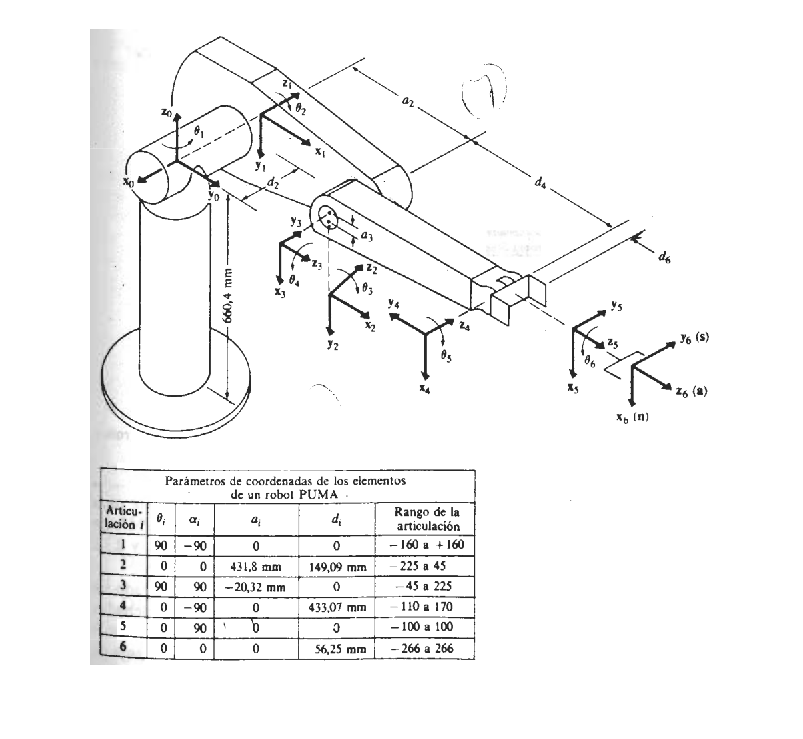

imshow("puma_fkine.png")

l1 = Link('revolute', 'offset',90, 'alpha',-90, 'a', 0, 'd', 0);
l2 = Link('revolute', 'offset',0, 'alpha',0, 'a', 431.8, 'd', 149.09);
l3 = Link('revolute', 'offset',90, 'alpha',90, 'a', -20.32, 'd', 0);
l4 = Link('revolute', 'offset',0, 'alpha',-90, 'a', 0, 'd', 433.07);
l5 = Link('revolute', 'offset',0, 'alpha',90, 'a', 0, 'd', 0);
l6 = Link('revolute', 'offset',0, 'alpha',0, 'a', 0, 'd', 56.25);
robot = SerialLink([l1 l2 l3 l4 l5 l6])

 
robot = 
 
noname:: 6 axis, RRRRRR, stdDH, slowRNE                          
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|        -90|         90|
|  2|         q2|     149.09|      431.8|          0|          0|
|  3|         q3|          0|     -20.32|         90|         90|
|  4|         q4|     433.07|          0|        -90|          0|
|  5|         q5|          0|          0|         90|          0|
|  6|         q6|      56.25|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


## Cinematica Inversa

### MTH

syms nx ny nz sx sy sz ax ay az px py pz
n = [nx ny nz]';
s = [sx sy sz]';
a = [ax ay az]';
p = [px py pz]';
rot = [n s a];
t06 = [rot p; [0 0 0 1]]

$$t06 = \left(\begin{array}{cccc} \bar{\mathrm{nx}} & \bar{\mathrm{sx}} & \bar{\mathrm{ax}} & \bar{\mathrm{px}}\\ \bar{\mathrm{ny}} & \bar{\mathrm{sy}} & \bar{\mathrm{ay}} & \bar{\mathrm{py}}\\ \bar{\mathrm{nz}} & \bar{\mathrm{sz}} & \bar{\mathrm{az}} & \bar{\mathrm{pz}}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### Configs

% BRAZO = ["derecho", "izquierdo"];
BRAZO = 1;
% CODO = ["arriba", "abajo"];
CODO = 1;
% MUNECA = ["abajo", "arriba"];
MUNECA = 1;
% FLIP, para decidir la orientacion de la muñeca
FLIP = 1;

### Primeras 3 articulaciones

syms px py pz d2 a2 a3 d4

#### Articulación 1

% -pi <= theta1 <= pi
theta1 = atan((-BRAZO*py*sqrt(px^2+py^2-d2^2)-px*d2) / (-BRAZO*py*sqrt(px^2+py^2-d2^2)+px*d2));

#### Articulación 2

R = sqrt(px^2 + py^2 + pz^2 - d2^2);
r = sqrt(px^2 + py^2 -d2 ^2);
senalpha = - pz / R;
cosalpha = - (BRAZO*r) / R;
cosbeta = (a2^2+R^2-(d4^2+a3^2)) / (2*a2*r);
senbeta = sqrt(1-(cosbeta)^2);
sentheta2 = senalpha*cosbeta+(BRAZO*CODO)*cosalpha*senbeta;
costheta2 = cosalpha*cosbeta-(BRAZO*CODO)*senalpha*senbeta;
% -pi <= theta2 <= pi
theta2 = atan(sentheta2 / costheta2);

#### Articulación 3

cosphi = (a2^2+(d4^2+a3^2)-R^2) / (2*a2*sqrt(d4^2+a3^2));
senphi = BRAZO*CODO*sqrt(1- cosphi^2);
senbeta = d4/sqrt(d4^2+a3^2);
cosbeta = abs(a3) / sqrt(d4^2+a3^2);
sentheta3 = senphi*cosbeta-cosphi*senbeta;
costheta3 = cosphi*cosbeta+senphi*senbeta;
% -pi <= theta3 <= pi
theta3 = atan(sentheta3 / costheta3);

### Últimas 3 articulaciones

s1 = sin(theta1);
s2 = sin(theta2);
s3 = sin(theta3);
s12 = sin(theta1+theta2);
s23 = sin(theta2+theta3);
c1 = cos(theta1);
c2 = cos(theta2);
c3 = cos(theta3);
c12 = cos(theta1+theta2);
c23 = cos(theta2+theta3);

#### Articulación 4

% -pi <= theta4 <= pi
theta4 = atan((MUNECA*(c1*ay-s1*ax)) / (MUNECA*(c1*c23*ax + s1*c23*ay - s23*az)));

#### Articulación 5

c4 = cos(theta4);
s4 = sin(theta4);
% -pi <= theta5 <= pi
theta5 = atan(((c1*c23*c4)*ax + (s1*c23*c4)*ay - c4*s23*az) / (c1*s23*ax + s1*s23*ay + c23*az));

#### Articulación 6

% -pi <= theta6 <= pi
theta6 = atan(((-s1*c4 - c1*c23*s4)*nx + (c1*c4 - s1*c23*s4)*ny + (s4*s23)*nz) / ((-s1*c4-c1*c23*s4)*sx + (c1*c4-s1*c23*s4)*sy + (s4*s23)*sz));

#### FLIP

if FLIP==1
    theta4 = theta4+pi;
    theta5 = -theta5;
    theta6 = theta6+pi;
end

## Número de posibles soluciones

Se tienen 8 posibles soluciones. Hay 4 soluciones para las 3 primeras articulaciones. Dos para la configuración del brazo del hombro derecho y dos para la configuración del brazo del hombro izquiero. Paracada configuración del brazo, se tiene un conjunto con FLIP desactivado y otro con FLIP activado.

## 4

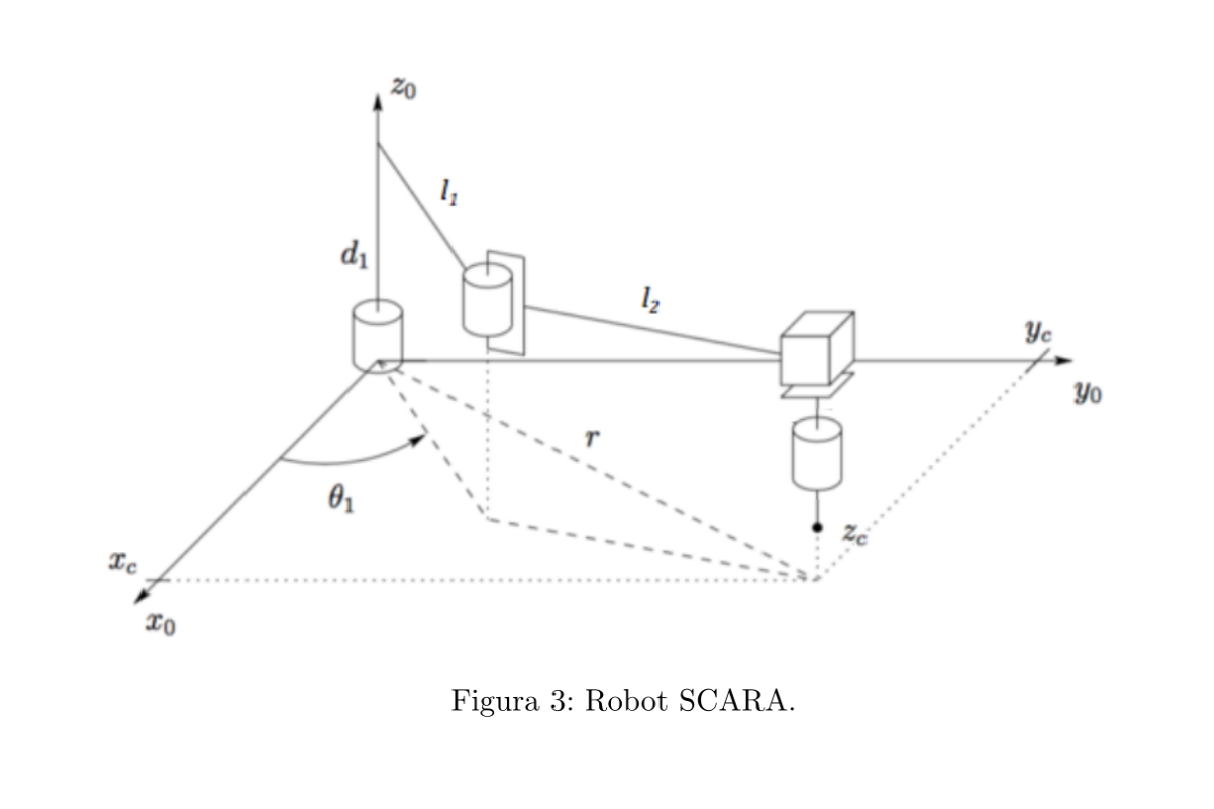

clc
clear
imshow("punto_4_enunciado.png")

### Cinematica inversa

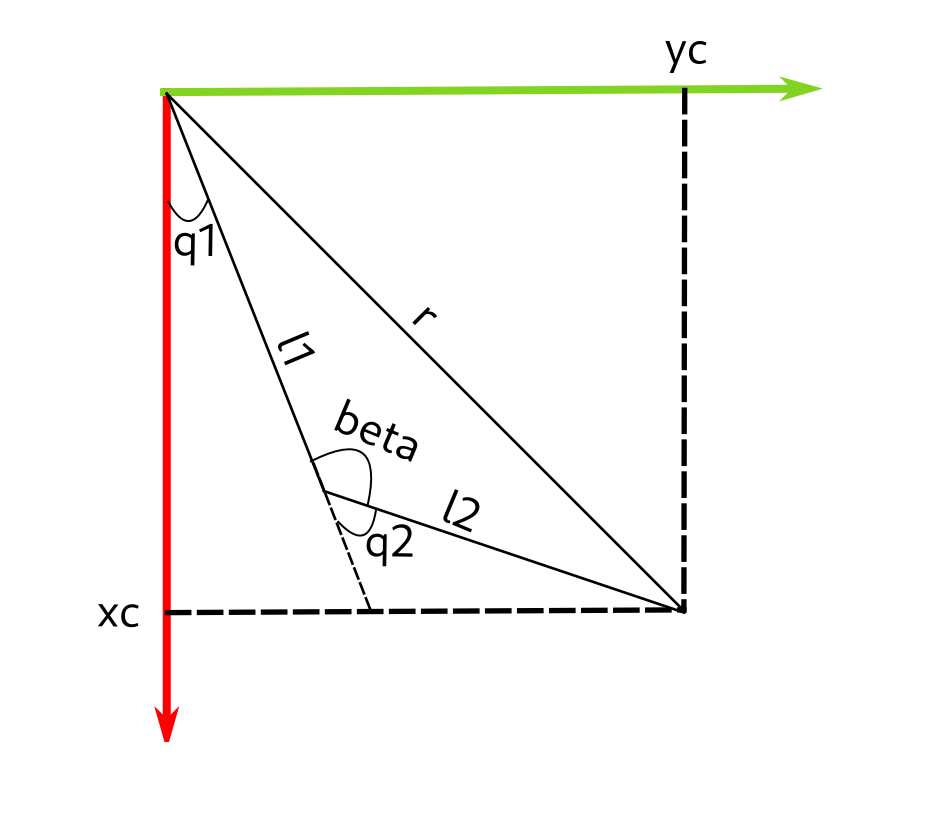

syms xc yc zc l1 l2 l3 d1 d4
imshow("punto_4.png")

r = sqrt(xc^2 + yc^2);
% se consiguen los angulos del triangulo con ley del coseno
calpha = (l1^2+r^2-l2^2)/(2*l1*r);
cbeta = (l1^2+l2^2-r^2)/(2*l1*l2);
cgamma = (l1^2+r^2-l1^2)/(2*l2*r);
% cos(180-theta2) = -cos(theta2)
c2 = -cbeta;
s2 = sqrt(1-c2^2);
theta2 = atan2(s2, c2);
theta1 = atan2(yc,xc) - atan2(l2*sin(theta2), l1+l2*cos(theta2));
% l3 es la distancia entre las arts 3 y 4
d3 = d1 -l3 - zc;
% para calcular theta4 es necesario conocer la matriz de transformación
% objetivo. no es suficiente con el vector posición
syms ny nx
% con la matriz de transformación 0T4. se puede ver que:
theta4 = -atan2(ny,nx) + theta1 - theta2;

### Grados de libertad independientes

Respecto a la posición en coordenadas cartesianas, el robot tiene 3 grados de libertad independientes. Las dos articulaciónes rotacionales permiten el movimiento libre en el plano xy. Y la articulación prismática puede moverse en el eje z independientemente de las otras dos.

Para la orientación en ángulos RPY, el robot tiene un solo grado de libertad independiente. La herramienta solo puede ser rotada al rededor de Yaw.

### Número de soluciones

Si se tiene en cuenta la orientación de la herramienta, existen 2 soluciones posibles para una ubicación dada. La solución depende de la articulación 2, también conocida como codo. Una de las soluciones tendrá el codo a la derecha y la otra a la izquierda.

Si solo se tiene en cuenta la ubicación, se tendrán infinitas soluciones. Esto se debe a que theta4 podrá tener cualquier valor y la ubicación será la requerida.

## 5

### a

clc
clear
syms xw yw zw l1

Primero, se consiguen los valores articulares para llegar a la posición w=[xw yw zw].

q1 = atan2(yw,xw);
q2 = atan2(zw-l1, xw^2+yw^2);
q3 = sqrt(xw^2+yw^2+(zw-l1)^2);

Ahora, se encontrará la matriz de revolución entre 3 y 6 para resolver la rotación:

link1 = Link ('revolute', 'd', l1, 'a', 0, 'alpha', pi/2, 'offset', pi/2);
link2 = Link ('revolute', 'd', 0, 'a', 0, 'alpha', pi/2, 'offset', pi/2);
link3 = Link ('prismatic', 'theta' , 0, 'a', 0, 'alpha', 0, 'offset', 0);
robot = SerialLink([link1 link2 link3]');
% se reescriben como matrices normalmes para poder indexar
a01 = trotz(q1) * transl([0; 0; link1.d]) * transl([link1.a; 0; 0]) * (trotx(link1.alpha));
a12 = trotz(q2) * transl([0; 0; link2.d]) * transl([link2.a; 0; 0]) * (trotx(link2.alpha));
a23 = trotz(link3.theta) * transl([0; 0; q3]) * transl([link3.a; 0; 0]) * (trotx(link3.alpha));
T = a01*a12*a23;
syms nx ox ax ny oy ay nz oz az q1 q2 q3
R = [nx ox ax; ny oy ay; nz oz az];
R36 = transpose(T(1:3,1:3))*R;

### B

q4 = atan2(R36(3,3),sqrt(1-R36(3,3)^2));
q5 = atan2(R36(1,3), R36(2,3));
q6 = atan2(-R36(3,1),R36(3,2));

### C

syms q1p1 q2p1 q3p1 q1p2 q2p2 q3p2
delta_q1 = q1p2 - q1p1;
delta_q2 = q2p2 - q1p1;
delta_q3 = q3p2 - q1p1;
delta_q1_i = delta_q1 / 15;
delta_q2_i = delta_q2 / 15;
delta_q3_i = delta_q3 / 15;
q1_interpolated = q1p1 + (1:15)*delta_q1_i;
q2_interpolated = q2p1 + (1:15)*delta_q2_i;
q3_interpolated = q3p1 + (1:15)*delta_q3_i;

## 6

### Algoritmo y ejemplo

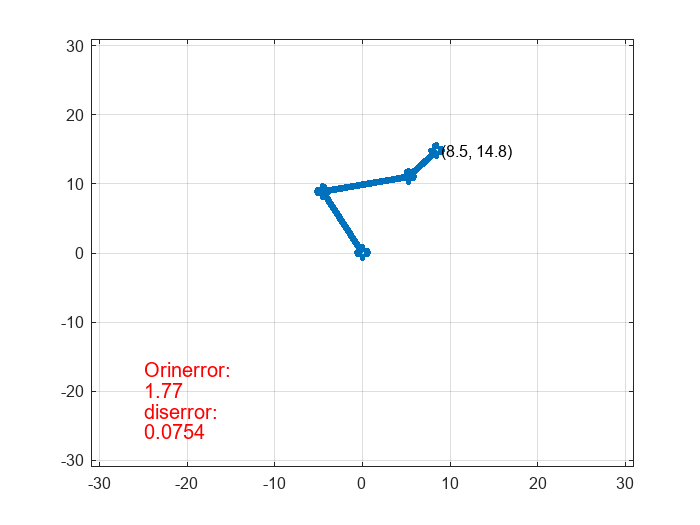

close all; clear;
theta1=0;d1=0;a1=10;alpha1=0;
theta2=0;d2=0;a2=10;alpha2=0;
theta3=0;d3=0;a3=5;alpha3=0;
deltatheta1=0;deltatheta2=0; deltatheta3=0;
Xc=8;Yc=15;
a=0;b=0;
while a==0
    while b==0
        theta1=theta1+deltatheta1/2;
        theta2=theta2+deltatheta2/2;
        theta3=theta3+deltatheta3/2;
        T01=DHmatrix(theta1,d1,a1,alpha1);
        T12=DHmatrix(theta2,d2,a2,alpha2);
        T23=DHmatrix(theta3,d3,a3,alpha3);
        T02=T01*T12;
        T03=T01*T12*T23;
        P0=[0 0];
        P1=transpose(T01(1:2,4));
        P2=transpose(T02(1:2,4));
        P3=transpose(T03(1:2,4));
        Q1=[P0(1,1) P1(1,1) P2(1,1) P3(1,1)];
        Q2=[P0(1,2) P1(1,2) P2(1,2) P3(1,2)];
        plot(Q1,Q2,'-o','LineWidth',4);
        axis([-31,31,-31,31]);
        grid on;
        Z0=[0;0;1];O=[0;0;0];O3=T03(1:3,4);
        Jv1=cross(Z0,(O3-O));
        Z1=T01(1:3,3);O1=T01(1:3,4);
        Jv2=cross(Z1,(O3-O1));
        Z3=T12(1:3,3);O2=T12(1:3,4);
        Jv3=cross(Z1,(O3-O2));
        Jv=[Jv1 Jv2 Jv3];
        Xinit=P3(1,1);Yinit=P3(1,2);
        Xend=Xc;Yend=Yc;
        Xspeed=(Xend-Xinit);
        Yspeed=(Yend-Yinit);
        thetadot=pinv(Jv)*[Xspeed;Yspeed;0];
        OrinEnd=atan2d(Yend,Xend);
        Orininit=atan2d(Yinit,Xinit);
        dis_error=sqrt(Xend^2+Yend^2)- sqrt(Xinit^2+Yinit^2);
        orin_error=OrinEnd-Orininit;
        if abs(dis_error)<=0.2 && abs(orin_error)<=2
            b=1;
        end
        theta1dot=thetadot(1,1);
        theta2dot=thetadot(2,1);
        theta3dot=thetadot(3,1);
        deltatheta1=rad2deg(theta1dot);
        deltatheta2=rad2deg(theta2dot);
        deltatheta3=rad2deg(theta3dot);
        deltatheta=[deltatheta1;deltatheta2;deltatheta3];
        text(P3(1,1),P3(1,2),[' (', num2str(P3(1,1),3), ', ', num2str(P3(1,2),3), ')']);
        text(-25,-17,'Orinerror:','Color','red','FontSize',12);
        text(-25,-20,num2str(abs(orin_error),3),'Color','red','FontSize',12);
        text(-25,-23,'diserror:','Color','red','FontSize',12);
        text(-25,-26,num2str(abs(dis_error),3),'Color','red','FontSize',12);
        pause(0.01);
    end
    if b==1
        b=0;
        break
    end
    break
end

### ikine6s

La función ikine6s forma parte de la Robotics Toolbox de Peter Corke para MATLAB. Se utiliza para realizar la cinemática inversa de un manipulador robótico de enlace en serie de 6 grados de libertad (6-DOF). La función calcula los ángulos de articulación (o configuraciones de articulación) necesarios para alcanzar una pose de efector final deseada (posición y orientación) en el espacio de trabajo del robot. A continuación se muestra una sintaxis general para utilizar la función ikine6s:

% q = ikine6s(robot, T, q0, máscara)

- robot es un objeto que representa el modelo del robot manipulador. Puede crearse utilizando la clase SerialLink de la Robotics Toolbox.

- T es la pose deseada del efector final representada por una matriz de transformación homogénea 4x4.

- q0 (opcional) es la estimación inicial de los ángulos de las articulaciones. Si no se especifica, la función utiliza un vector cero como estimación inicial.

- mask (opcional) es un vector binario que especifica qué ángulos de articulación deben considerarse en la solución. Un valor de 1 indica que el ángulo de la articulación se incluye, mientras que 0 indica que el ángulo de la articulación se ignora. Si no se especifica, se consideran todos los ángulos de articulación.

La función ikine6s utiliza métodos numéricos, como algoritmos de cinemática inversa y técnicas de optimización, para encontrar los ángulos de articulación que mejor se ajustan a la pose deseada del efector final. El resultado es un vector q que contiene los ángulos de las articulaciones del robot manipulador. Cabe destacar que la función ikine6s asume un manipulador robótico de 6-DOF con articulaciones prismáticas o de revolución. Proporciona una forma eficaz y cómoda de resolver problemas de cinemática inversa en MATLAB para este tipo específico de robot.

Si tienes un robot de 6-DOF con articulaciones de revolución o prismáticas, es probable que puedas utilizar la función ikine6s directamente. Sin embargo, si tú robot tiene una configuración diferente o complejidades adicionales como tipos de articulaciones especializadas (por ejemplo, articulaciones esféricas) o restricciones, es posible que sea necesario modificar o ampliar la función ikine6s o implementar un solucionador de cinemática inversa personalizado adaptado al robot específico.

Es importante tener en cuenta que la aplicabilidad de la función ikine6s depende de la estructura cinemática y las limitaciones de su robot. Si su robot se desvía significativamente de las suposiciones realizadas por la función ikine6s, es posible que tenga que explorar enfoques o algoritmos alternativos para resolver el problema de la cinemática inversa para la configuración específica de su robot.

function [Mdh] = DHmatrix(theta,d,a,alpha)
    Mdh=[cosd(theta) -sind(theta)*cosd(alpha) sind(theta)*sind(alpha) a*cosd(theta);
    sind(theta) cosd(theta)*cosd(alpha) -cosd(theta)*sind(alpha) a*sind(theta);
    0,sind(alpha),cosd(alpha),d;
    0,0,0,1];
end